# Mapeo De Funciones

1) Se genera una matriz con los valores de la imagen original y la graficamos.

M=imread('test.jpg');

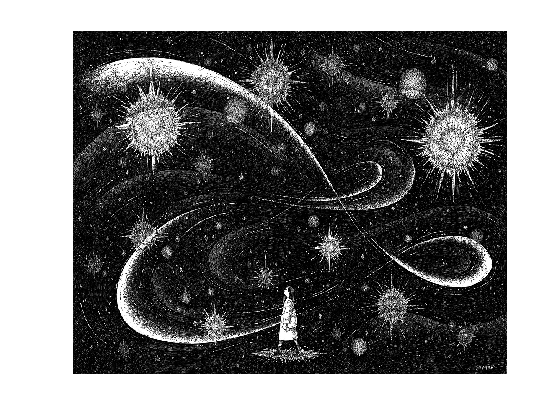

figure
imagesc(M)
axis off
colormap gray

2) Definimos la Transformación.

f = @(z) (z)^(1/8);

[sm,sn] = size(M);

[x,y] = meshgrid(linspace(0,2*pi,sm),linspace(0,2*pi,sn));
Z = x+y*1i;

f = @(z) exp(z);

Zt = f(Z);

re = real(Zt);
im = imag(Zt);

x = reshape(re,1,[]);
y = reshape(im,1,[]);
int = reshape(M,1,[]);

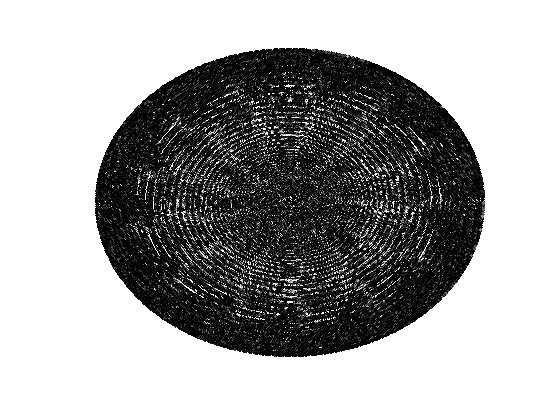

figure
scatter(x,y,5,int,'filled')
set(gca,'Color','g')
axis off
colormap gray